%EstimatedPosePlotter.m
%Author: Stig Turner
%Mail: sttur14@student.sdu.dk


## Init

%connect to roscore or start a new one
clc; clear;
rosshutdown; %if connected to ros core then disconnect
rosinit; %connect to roscore (fails if allready connected)

Initializing global node /matlab_global_node_39312 with NodeURI http://hp:50868/


%create subscriber for the estimated pose
estimatedPose = rossubscriber('/monocular_pose_estimator/estimated_pose'); 
number_of_samples = 100;


## Recive data

for n = 1:number_of_samples
poseData = receive(estimatedPose,5);

PosData(n,1) = poseData.Pose.Pose.Position.X;
PosData(n,2) = poseData.Pose.Pose.Position.Y;
PosData(n,3) = poseData.Pose.Pose.Position.Z;
QOriData(n,1) = poseData.Pose.Pose.Orientation.X;
QOriData(n,2) = poseData.Pose.Pose.Orientation.Y;
QOriData(n,3) = poseData.Pose.Pose.Orientation.Z;
QOriData(n,4) = poseData.Pose.Pose.Orientation.W;
end
%Shutdown or disconnect from roscore
rosshutdown;

Shutting down global node /matlab_global_node_39312 with NodeURI http://hp:50868/


%Calc orientation in Eular
EuOriData = quat2eul(QOriData);


## Plot data

% figure
% px = plot(PosData(:,1),'r');
% hold on;
% py = plot(PosData(:,2),'g');
% hold on;
% pz = plot(PosData(:,3),'b');
% ylim([min(min(PosData))-0.1 , max(max(PosData)) + 0.2]);
% title('Position')
% xlabel('Sample nr.')
% ylabel('Meter')
% hold off


## Plot X,Y,Z,Pitch,Roll,Yaw

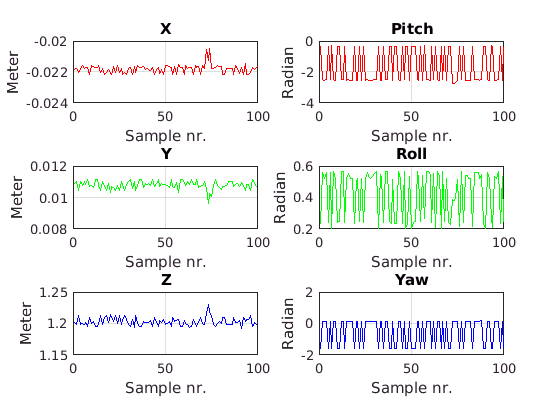

figure
ax = subplot(3,2,1);
plot(PosData(:,1),'r')
grid(ax,'on')
xlabel('Sample nr.');
ylabel('Meter');
title('X')

ax = subplot(3,2,3);
plot(PosData(:,2),'g')
grid(ax,'on')
xlabel('Sample nr.')
ylabel('Meter')
title('Y')

ax = subplot(3,2,5);
plot(PosData(:,3),'b')
grid(ax,'on')
xlabel('Sample nr.')
ylabel('Meter')
title('Z')

ax = subplot(3,2,2);
plot(EuOriData(:,1),'r')
grid(ax,'on')
xlabel('Sample nr.')
ylabel('Radian')
title('Pitch')

ax = subplot(3,2,4);
plot(EuOriData(:,2),'g')
grid(ax,'on')
xlabel('Sample nr.')
ylabel('Radian')
title('Roll')

ax = subplot(3,2,6);
plot(EuOriData(:,3),'b')
grid(ax,'on')
xlabel('Sample nr.')
ylabel('Radian')
title('Yaw')

## Plot 3D of path

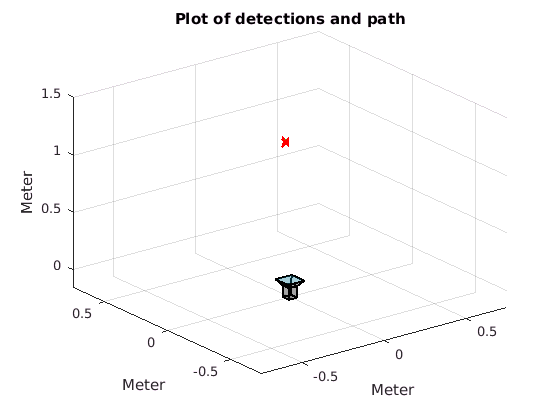

figure;
scatter3(PosData(:,1),PosData(:,2),PosData(:,3),'x','r');
hold on
plot3(PosData(:,1),PosData(:,2),PosData(:,3),'g');
hold on
xlabel('Meter');
ylabel('Meter');
zlabel('Meter');
title('Plot of detections and path');
xlim([-0.75,0.75]);
ylim([-0.75,0.75]);
zlim([-0.15,1.5]);
R = [1 0 0; 0 1 0; 0 0 1];
plotCamera('Location',[0 0 -0.10],'Orientation',R,'Size',0.05,'Color',[0,0,0]);

## Close up orientation plot

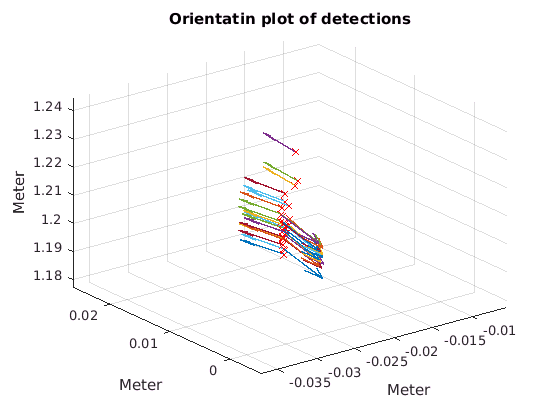

figure
[m,n] = size(PosData);
scatter3(PosData(:,1),PosData(:,2),PosData(:,3),'x','r');
hold on
for(c = 1:m)
R = eul2rotm(EuOriData(c,:));
vec = [0 0 0.01] * R;
quiver3(PosData(c,1),PosData(c,2),PosData(c,3),vec(1),vec(2),vec(3),'LineWidth',1,'MaxHeadSize',1);
hold on
end
xlabel('Meter');
ylabel('Meter');
zlabel('Meter');
title('Orientatin plot of detections');
xlim([min(PosData(:,1))-0.015,max(PosData(:,1))+0.015]);
ylim([min(PosData(:,2))-0.015,max(PosData(:,2))+0.015]);
zlim([min(PosData(:,3))-0.015,max(PosData(:,3))+0.015]);